# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 5 Statistics

% allow matlab to look for additional functions in a directory called codes
addpath ../codes
addpath ../data

## 5.1 What is statistics?

Statistics quite simply is the study of populations: their distributions and their relationships to other populations.  By populations I really just mean sample sets.  A ***statistic*** is any single value that is used to describe some aspect of a distribution.  In Chapters 1 and 2, we looked at a number of statistics for several distributions, e.g., mean, median, and standard deviation.  A ***test statistic*** is a metric that is used to ask a question, which we call hypothesis testing.

The hypothesis we are testing is called the ***null hypothesis***, which generally states that there is no difference between two populations (one can be ideal).  It is unlikely that you will find zero difference, so we often place a constraint that the two populations are equivalent within some specified level of uncertainty.

### 5.1.1 Order Statistics

Some statistical methods require the use of order statistics, which require the data to be ordered (or sorted) from smallest to largest.  For example, to compute an empirical cumulative distribution function, the data must be ordered.  Suppose you collected 5 values, $X = \{9, 17, 2, 11, 8\}$. In the original sampled data, we would identify the first sample as $x_1 = 9$.  In the ordered sample set, $x_{(1)} \leq x_{(2)} \leq \ldots \leq x_{(N)}$ where $(i)$ it identify the $i$-th order value, e.g., the first order sample is $x_{(1)} = 2$.  Thus the ordered values of $X \to X_* = \{2, 8, 9, 11, 17 \}$. 

### 5.1.2 Rank-Order Statistics

In some of the statistical models below, we will use robust methods that attempt to improve statistical estimates or reliability of significance tests in the presence of outliers.  Many robust statistical methods don't use data directly, but instead use rank-ordered variables associated with the original dataset.  The rank is the index of the ordered sample set, with respect to the original sample values.  From our example on order statistics above,


$$\begin{array}{cccc} i & x_i & x_{(i)} & r_i \\ 1 & 9 & 2 & 3 \\ 2 & 17 & 8 & 5 \\ 3 & 2 & 9 & 1 \\ 4 & 11 & 11 & 4 \\ 5 & 8 & 17 & 2 \end{array}$$


where $i$ is the index of the original sample set, $x_i$ is the original sample set values, $x_{(i)}$ is the ordered sample set, and $r_i$ is the rank associated with the original unordered sample set. The sample, ordered sample, and rank-order are related by $x_i = x_{(r_i)}$.

## 5.2 Covariance and Correlation

### 5.2.1 Covariance

The covariance is a measure of the variability of two paired (equal number of samples) random variables, $X$ and $Y$,


$$\text{Cov}(X,Y) = \frac{1}{N}\sum_{i=1}^N (x_i - \bar{x}) (y_i - \bar{y})$$


### 5.2.2 Correlation

A correlation is a normalized measure of the covariance.  The correlation coefficient can theoretically range from [-1,1], where -1 indicates a negative or anticorrelation that will be fit by a line with a negative slope and +1 is a positive correlation that will be fit by line with a positive slope.   A value of zero indicates 0 correlation.  

A correlation between two sample sets does not imply a causal relationship. Two sample sets can be highly correlated, but the ultimate question of causality cannot be determined by statistics.  A classic example is the correlation between ice cream sales and crime rate.  Ice cream does not cause people to commit crimes and criminals do not necessarily enjoy a cold treat after committing dastardly acts.  Hot weather brings people to the beach, where ice cream parlors then enjoy higher sales from increased traffic.  The simple fact that more people are around raise the incident of opportunistic crimes such as purse snatching and testosterone-driven crimes like assault.

To establish causality, you need a physical model not a linear or polynomial relationship, though the physical relationship can have a linear or polynomial form.  The correlation models presented below are for linear models, but correlations can be extended to a wider range of models, many simply by linearizing (see Regression chapter).  The simplest correlation coefficient is Pearson's correlation, but it susceptible to outliers.

#### 5.2.2.1 Pearson's correlation

The correlation coefficient is related to the covariance by


$$\text{Corr}(X,Y) = r = \frac{\text{Cov}(X,Y)}{\text{Var}(X) \text{Var}(Y)}$$


This definition for correlation is also known as the Pearson's $r$-value.

Below are a correlation coefficients for a random variable $X$ and a variable $y$ that is computed by a linear model as a function of $x$, with an additional random perturbation of various sizes, $\sigma_y$, to obscure the initial linear relationship.

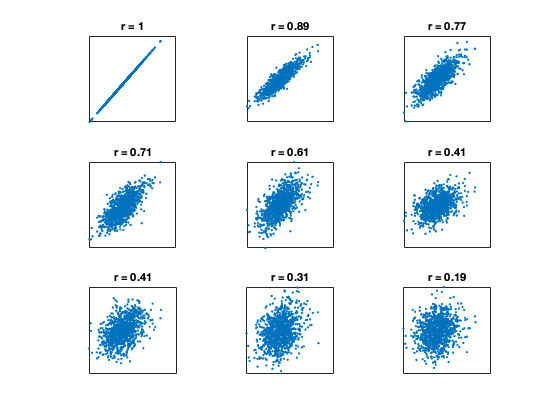

clear all;

N = 1000; % number of samples for x and y

% create a random variable x
x = randn([N 1]);

% create a variable y that is linear related to x
y = x;

figure;

% add an additional uncertainty to y, this reduces the correlation.
sigmay = [0 0.5 0.8 1 1.25 2 2.5 3 6];
%sigmay = [0 0.125 0.25 0.5 1 2 4 8 16];
for i = 1:length(sigmay)
    % add uncertainty to y values
    yp = y + sigmay(i)*randn([N 1]);
    
    % compute Pearson's correlation coefficient
    r = sum((x - mean(x)).*(yp - mean(yp)))/(N*std(x)*std(yp));
    
    % plot X vs. Y
    subplot(3,3,i);
    plot(x,yp,'.');
    title(['r = ',num2str(r,2)]);
    axis square;
    set(gca,'XTick',[],'YTick',[]);
end

At what point does the linear correlation cease to have meaning, 0.7, 0.5, or 0.3?  It can be difficult to tell exactly and may depend on the type of system under study.  Some systems are inherently complex and there may be low correlation coefficients that can still be deemed acceptable (e.g., paleoclimate, biologic) and others where the processes are more straightforward and a low correlation coefficient, $|r| <$0.5, would be considered a poor result.

#### 5.2.2.2 Spearman's rank correlation

One problem with the common Pearson's formulation is that outliers heavily affect the calculation.  Therefore a more robust correlation coefficient is desired.  Spearman's rank correlation and the robust version below solve this problem by using rank-order variables, which are then used to compute the correlation coefficient.  To rank order a vector, the values are sorted in ascending order and then replaced by their position in the sequence.  For each set of duplicate values, the rank value is an average of the positions for the duplicate values.  Both $x$ and $y$ are independently mapped to rank-order variables, $X \mapsto U$ and $Y \mapsto V$.  The Spearman's rank correlation coefficient is then computed in a manner similar to Pearson's formula,


$$\rho = \text{Corr}(U,V) =  \frac{\sum_{i=1}^N(u_i - \bar{u})(v_i - \bar{v})}{\sum_{i=1}^N\sqrt{(u_i - \bar{u})}\sum_{i=1}^N\sqrt{(v_i - \bar{v})}}$$


Another formulation commonly used to compute the Spearman's rank correlation coefficient is given by


$$\rho = 1 - \frac{6}{N(N^2 - 1)}\sum_{i = 1}^N ( u_i - v_i)^2}{N (N^2 - 1)}$$


clear all;

% number of samples (if you increase it, I would comment out the [X,Y] line
N = 10;

% create a random variable x
X = randn([N 1]);
% create a random variable y that has a linear relationship with x
sigmay = 0.2;
Y = X + 0.2*randn([N 1]);

[X,Y]

ans =     2.9080    2.8372
    0.8252    0.6605
    1.3790    1.0636
   -1.0582   -0.9566
   -0.4686   -0.4122
   -0.2725   -0.2658
    1.0984    0.8317
   -0.2779   -0.0524
    0.7015    0.7716
   -2.0518   -2.1116



% rank the vectors
% If all the values are unique the rank order of X can be determined from
% the index of sort (see sort).  If all the ranks are not unique then ranks
% need to be adjusted (see rankvec).
R(:,1) = rankvec(X);
R(:,2) = rankvec(Y);

% associate 
R = sortrows(R);
u = R(:,1);
v = R(:,2);

% method 1:
rho = sum((u - mean(u)).*(v - mean(v)))/((N-1)*std(u)*std(v))

% method 2:
rho = 1 - 6*sum((u - v).^2)/(N*(N^2 - 1))

rho = 0.9758

r = 0.9758

#### 5.2.3.3 Kendall's rank correlation

Another rank correlation was devised by Kendall.  It more computationally intensive than Spearman's rank because it examines every permutation of points.  It in simple terms, it can be described as


$$\tau = \frac{2}{n(n-1)}[(\text{No. of concordant pairs}) - (\text{No. of discordant pairs})]$$


where a pair of points $(x_i, y_i)$ and $(x_j,y_j)$ are concordant when $x_i < x_j$ and $y_i < y_j$ or $x_i > x_j$ and $y_i > y_j$ and discordant when $x_i < x_j$ and $y_i > y_j$ or $x_i > x_j$ and $y_i < y_j$.  Values where $x_i = x_j$ or $y_i = y_j$ are neither concordant or discordant.  Because it does not depend upon the values only whether a value is greater or less than zero, we can use the sign function, $\text{sgn}$, which is -1 when the argument is negative and 1 when the argument is positive.  Kendall's rank can be written as


$$\tau = \frac{2}{n(n-1)}\sum_{i<j} \text{sgn}(x_i - x_j)\text{sgn}(y_i - y_j)$$


An example calculation is shown below.

clear all;

% number of samples (if you increase it, I would comment out the [X,Y] line
N = 10;

% create a random variable x
X = randn([N 1]);
% create a random variable y that has a linear relationship with x
sigmay = 0.2;
Y = X + 0.2*randn([N 1]);

[X,Y]

ans =    -0.1022   -0.2750
   -0.2414   -0.2260
    0.3192    0.0764
    0.3129    0.0902
   -0.8649   -0.8662
   -0.0301    0.2765
   -0.1649   -0.3188
    0.6277    0.7020
    1.0933    1.0481
    1.1093    1.3327



% construct a matrix where each column is a copy of x
A = repmat(X,1,N);
% determine the sign of paired differences by taking the transpose of A
% note we only need the upper triangular matrix
A = A - A';
% construct a matrix where each column is a copy of x
B = repmat(Y,1,N);
% determine the sign of paired differences by taking the transpose of A
% note we only need the upper triangular matrix
B = B - B';

% determine the number of concordant pairs
cp = sum(triu((A < 1 & B < 1) | (A > 1 & B > 1) & ~(A == 0 | B == 0),1),'all');
% determine the number of disconcordant pairs
dp = sum(triu((A < 1 & B > 1) | (A > 1 & B < 1) & ~(A == 0 | B == 0),1),'all');

% compute Kendall's correlation coefficient
tau = 2*(cp - dp)/(N*(N-1))

tau = 0.9111

#### 5.2.2.4 Robust correlation methods

Robust methods require the statistical removal of outliers or use Monte Carlo-based algorithms to estimate parameters.  The Monte Carlo methods typically take a random subset of samples and compute a result, and then repeat the process many more times.  The advantage of such a procedure is that they tend to give more accurate estimates of the desired statistic.  Such methods also provide a PDF for the desired statistic from which uncertainty can also be assessed.  None of the other correlation methods above can do that.

### 5.2.3 Quantile–quantile (Q–Q) plot

A Q-Q plot is a method that can be used to visually compare two distributions.  If two distributions are identical, they will fall along a line.  If the points fall below the line on the left end of the quantiles, then the y-axis samples are skewed towards lower values than the x-axis samples.  If the points fall above the line on the right end of the quantiles, then the y-axis samples are skewed towards high values than the x-axis samples.

In the example below, the heat production of subalkalic basalt are long tailed towards high values and short tailed towards low values than one would expect for a normally distributed data.  Once taking the log of the basaltic heat production, we find the distribution is closer to normal (in log-space).

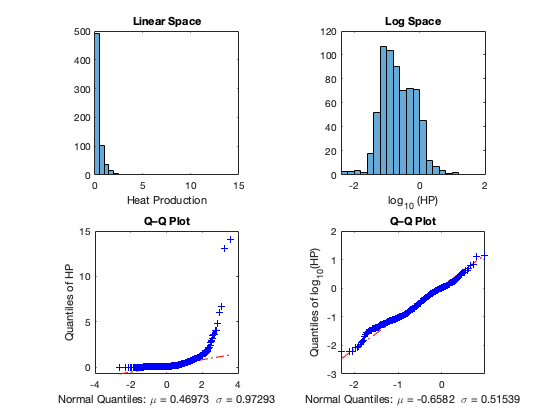

clear all;

% load Australian heat production dataset
data = readtable('australian_hp.csv','Format','%s%f%f%f');

% filter to find only granites
% (and add geographic bounds to remove some stray points)
ind = strcmp(data.rock_type,'subalkalic basalt') & -45 < data.latitude & data.latitude < -10 & 110 < data.longitude & data.longitude < 155;

% make our dataset contain only the granites (otherwise it is quite large)
HP = data.heat_production(ind);

figure;
subplot(221);
histogram(HP,'BinWidth',0.5);
xlabel('Heat Production');
title('Linear Space');
axis square;

mu = mean(HP);
sigma = std(HP);

subplot(223);
h = qqplot(HP,makedist('Normal','mu',mu,'sigma',sigma));
title('Q–Q Plot')
ylabel('Quantiles of HP');
xlabel(['Normal Quantiles: \mu = ',num2str(mu),'  \sigma = ',num2str(sigma)]);
axis square;
set(gca,'Box','on');

subplot(222);
histogram(log10(HP));
xlabel('log_{10} (HP)');
title('Log Space');
axis square;

mu = mean(log10(HP));
sigma = std(log10(HP));

subplot(224);
qqplot(log10(HP),makedist('Normal','mu',mu,'sigma',sigma));
ylabel('Quantiles of log_{10}(HP)');
xlabel(['Normal Quantiles: \mu = ',num2str(mu),'  \sigma = ',num2str(sigma)]);
title('Q–Q Plot')
axis square;
set(gca,'Box','on');

## 5.3 Confidence

### 5.3.1 Confidence Interval

You collect a set of samples and compute their mean and standard deviation.  Presumably, if you could repeat the same experiment again with the same number of samples, you would achieve a different set of scale parameters. But of course you can't perform the test again, so how confident are you in the scale factors you determined?  A confidence interval is the probability that the true mean is contained within these bounds with a cumulative probability of confidence level of $1-\alpha$, where $\alpha \in (0,1)$.  It is still possible that the true mean still lies outside these bounds with a probability of $\alpha$.  Often $1 - \alpha$ will be expressed as a percentage rather than a decimal.

A confidence interval represents the cumulative probability that a sample will fall between a given range of values, i.e., the area beneath a probability distribution function between the confidence bounds.  For a normal distribution with known scale parameters, the area between $[-x,x]$ is


$$A(x) = \text{erf} \left( \frac{x - \mu}{\sigma} \right) = \frac{2}{\sqrt{\pi}} \int_\mu^{x+\mu} \exp \left(-\frac{(x\prime - \mu)^2}{\sigma^2} \right) \ dx\prime$$


This area differs slightly from a cumulative distribution function in that it is referenced to the mean, not the left bound of the distribution.  But we wish to know the values of $x$ associated with a given value of $A = 1-\alpha$, which requires the inverse of this function, i.e., $x(A)$.  However, we are working with real data, so we approach the problem a little differently.  As we will see in the section on $t$-tests (Section 5.4.2), we can relate the estimated mean to the true mean using the $t$-statistic with $N - 1$ degrees of freedom,


$$t_{N-1} = \frac{\bar{x} - \mu}{s(N)^{-1/2}}$$


where $\mu$ is the true mean, $\bar{x}$ is the sample mean, $s$ is the sample standard deviation, and $N$ is the number of samples.  Solving for $\mu$, and inverting for $t_{N-1}$ for the $1-\alpha/2$ quantile of a $t$-distribution with $N-1$ degrees of freedom, we can determine the confidence bounds on the true mean,


$$x_{\pm \alpha/2} = \bar{x} \pm t_{N-1,1 - \alpha/2}\frac{s}{\sqrt{N}}$$


When $N$ is large, the observed distribution converges towards the true distribution, allowing us to approximate $t_{N-1,1 - \alpha/2}$ from the quantiles, $z_{\alpha/2}$ for the normal distribution.  For large $N$,


$$x_{\pm \alpha/2} \approx \bar{x} \pm z_{\alpha/2}\frac{s}{\sqrt{N}}$$


Values of $z_{\alpha/2}$ are listed for common confidence levels in the Table below.


$$\begin{array}{ccc} \text{C.L. (\%)} & \alpha & z_{\pm \alpha/2} \\ 90 & 0.1 & 1.645 \\ 95 & 0.05 & 1.960 \\ 99 & 0.01 & 2.576 \end{array}$$


You will often see a mean values reported as $\bar{x} \pm 2 s$ in papers, which are approximately the 95% confidence bounds for large samples sizes; although, it tends to get used for any sample size in the literature.

We can use a similar procedure to find the confidence bounds on the true variance, which requires values from the $\chi^2$-distribution,


$$s_{\pm \alpha/2} = \left[\frac{(n - 1)s^2}{\chi^2_{n-1,1-\alpha/2}}, \frac{(n - 1)s^2}{\chi^2_{n-1,\alpha/2}} \right]$$


which for large $N$ is approximately,


$$s_{\pm \alpha/2}^2 = s^2 \left(1 \pm |z_{\alpha/2}|\sqrt{\frac{2}{N}} \right)$$


### 5.3.2 Level of Significance

Levels of significance, or 1 – confidence level, come in two flavors one-tailed (right or left) and two-tailed (right and left).  The significance level represents the total probability, or area of the tail.  For the left tail,


$$L(x) = \int_{\xi}^{x} P(x\prime)\ dx\prime$$


where $P(x)$ is a generic probability distribution and $x \in [\xi,\infty)$ for which $\xi$ is essentially the lower bound of allowable $x$ values.  For a Gaussian $\xi \to -\infty$, but for a log-normal $\xi \to 0$.  Note, $L$ is equivalent to the cumulative distribution function, $C(x)$.  For a right tail,


$$R(x) = \int_{x}^{\infty} P(x\prime)\ dx\prime$$


Generally, we work the problem the other way around.  We want to know the value of $P(x)$ for which $L(x) = 1 - \alpha$ or $R(x) = 1 - \alpha$ for left- and right-tailed tests, respectively, or when $L(x) = R(x) = 1 - \alpha/2$ for two-tailed tests.  In both cases, $\alpha$ is our desired level of significance and $1 - \alpha$ is the area in the tail for a one-tailed test and $1 -\alpha/2$ is the area in each respective tail for a two-tailed test.  Thus we want the inverse of $L$ and $R$.  Since $L$ is the CDF, it is almost always easiest to determine the inverse CDF, $C^{-1}$, which also happens to be the quantile function, $Q$ so we can reformulate $R = 1 - \alpha = 1 - L$, e.g., $R = 0.05$, $L = 1 - 0.05 = 0.95$.  To find $x$ associated with the desired significance, $x_L = Q(1 - \alpha)$ and $x_R = Q(\alpha)$ for the left and right sides of a one-tailed test, respectively and $x_L = Q(1 - \alpha/2)$ and $x_R = Q(\alpha/2)$ for the left and right sides of a two-tailed test.

Note, quantile functions are notoriously difficult to compute, and some have no or as yet defined analytic form, thus relying on look-up tables or approximations.  For example, the $t$-distribution does not have an analytic form.

### 5.3.3 *p*-Values

Sellke et al., 2001 in a study of how p-values relate to the probability of rejecting a null hypothesis, write: "The most important conclusion is that, for testing "precise" hypotheses, $p$ values should not be used directly, because they are too easily misinterpreted. The standard approach in teaching—of stressing the formal definition of a $p$ value while warning against its misinterpretation—has simply been an abysmal failure."  This statement is probably the most strongly worded cautionary conclusion I have ever read.  There is a reason a number of journals have decided that $p$-values cannot be used as the only basis for interpreting results, and a few journals have banned the use of $p$-values altogether.  However, that does not mean that $p$-values are not useful, only that one should be very cautious in their use and be aware of what they represent and what they do not.

Assuming the null hypothesis (our test) is true, **a **$p$**-value is the probability that we will obtain a sample set at least as extreme as our observations**.  A high $p$-value suggests that the null hypothesis is correct (our observations are drawn from the proposed true distribution).  A low $p$-value suggests that our null hypothesis is incorrect.

Suppose you go to measure some observable $x$, collecting $N$ discrete observations to generate the sample set $\bf X_{\text{obs$}}$.  Our observations are only one of any possible random sample set $\bf X$.  We will entertain a hypothesis (called the null hypothesis which we indicate by $H_0$) that $\bf X$ is drawn from the continuous and true distribution $P(x)$.  We can create a test statistic $T({\bf X})$ to explore the compatibility of our observations with $H_0$.  Large values of $T$ are less compatible with $H_0$.  The $p$-value is a probability,

$p = \text{Pr}(T({\bf X}) \geq T({\bf X_{\text{obs}}}))$,

which is to say it is how often we will obtain a value $T({\bf X_{\text{obs}}})$ at least as extreme $(\leq)$ as any of those found by repeated $T({\bf X})$ experiments.  It also represents the survival probability, $1 - \text{CDF}(T({\bf X_{\text{obs}}}))$.  Don't worry, we will look at all of this in more detail.

**A **$p$**-value is not the probability of error in rejecting a null hypothesis.**  In reality, the probability is signfiicantly higher that the null hypothesis will be incorrectly rejected on the basis of a given $p$-value.  The actual error rate can be estimated by two methods,


$$\begin{array}{rcl} B(p) & = & -e p \log (p) \\ A(p) & = & B(p)(1 + B(p))^{-1} \end{array}$$


where $e$ is the natural number, B(p) is the lower bound on the probability of incorrectly rejecting the null hypothesis, and a(p) is a more likely estimate of being in error.  For the common $p$-value of 0.05 you can clearly see from the figure below that there is between a 29 and 41% probability the null hypothesis is rejected in error using the two respective error model.  Not great odds.

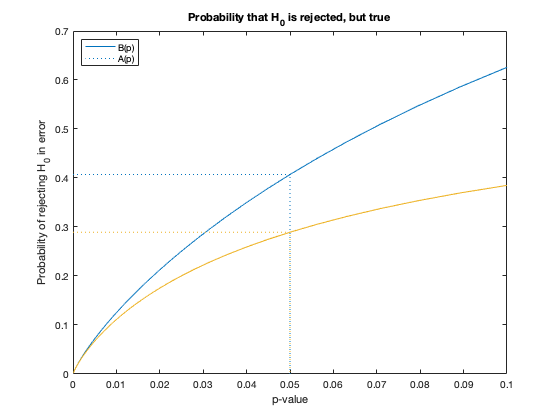

clear all;

% p-value
p = 10.^[-4:0.05:-1];

% lower bound, B(p)
B = -exp(1)*p.*log(p);
B005 = -exp(1)*0.05.*log(0.05);
% type 1 error (rejection of true null hypothesis).
A = B./(1 + B);

A005 = B005/(1 + B005);

figure;
hold on;
h = plot(p,B);
plot([0 0.05 0.05],B005*[1 1 0],':','Color',get(h,'Color'));
h = plot(p,A);
plot([0 0.05 0.05],A005*[1 1 0],':','Color',get(h,'Color'));
title('Probability that H_0 is rejected, but true');
xlabel('p-value');
ylabel('Probability of rejecting H_0 in error');
legend('B(p)','A(p)','Location','northwest');
set(gca,'Box','on');

## 5.4 Hypothesis Testing

### 5.4.1 How Hypothesis Testing Works

As we analyze data, we often want to know how they relate to other data; typically, do two sample sets come from the same or distribution/population.  This question cannot be answered definitively but can be offered with a degree of confidence or significance by performing a hypothesis test.  There are two types of tests: (1) ***parametric*** tests assume that data are drawn from a specified distribution; and ***non-parametric*** tests do not assume a particular distribution.  Parametric tests are considered more powerful, but more data are necessary for the test to produce valid results, typically greater than 15 to 20 samples in each sample set or group.  Non-parametric tests however, work better when the median provides a better measure for the central tendency than the mean for a sample distribution (e.g., among highly skewed distributions).  Non-parametric tests can also be performed with rank-ordered data, and are therefore, less influenced by outliers than parametric tests.

Hypothesis tests are generally used to test whether one mean or variance collected for one sample set differs from the mean or variance of another, either ideal or from a second sample set.  We construct two hypotheses: (1) the ***null hypothesis*** ($H_0$) generally states that two statistics are equivalent, either from one sample set and a known value, or from two sample sets; and (2) the ***alternative hypothesis*** ($H_1$) states that two statistics are different.  To perform a hypothesis test, we start by computing a test statistic.  A ***test statistic*** is a standardized statistic that has a known probability distribution (e.g., t-distribution, F-distribution, etc.) that simplifies our ability to assess the null hypothesis.  The distribution of a test statistic represents the distribution of values that one could expect if one collected a large number of sample sets of equal size from a large population, i.e., if the null hypothesis were true.  Because we sample a finite number of samples, not the entire population, the distribution for the test statistic generally incorporates the number of samples (or degrees of freedom) collected into its shape.  Shown below is a t-distribution.

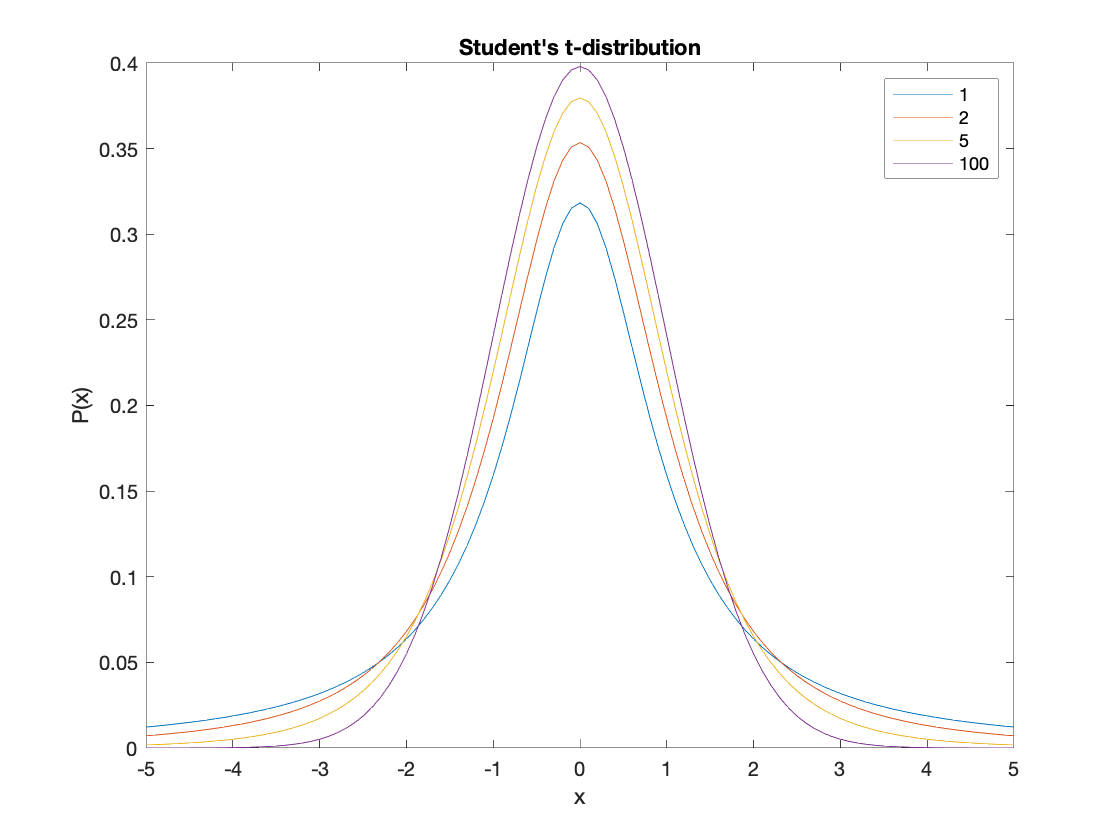

clear all;

% degrees of freedom
nu = [1 2 5 100];

x = [-5:0.1:5];

for i = 1:length(nu)
    % compute a t-distribution for nu(i) degrees of freedom
    P(i,:) = gamma((nu(i)+1)/2) / (sqrt(nu(i)*pi) * gamma(nu(i)/2)) * ... 
        (1 + x.^2/nu(i)).^-((nu(i) + 1)/2);
    % PN: ... allows me to continue lines on the next line without breaking
    % the program.  It can be used to improve readability.
end

figure;
plot(x,P);
for i = 1:length(nu)
    ltxt{i} = num2str(nu(i));
end
legend(ltxt);
xlabel('x');
ylabel('P(x)')
title('Student''s t-distribution');

Notice that for Student's t-distribution as the number of degrees of freedom increase the width of the distribution becomes narrower (short-tailed).  This behavior means that as we collect more samples the two means will need to be closer in order to accept the null hypothesis.

Although we show how the statistics are computed below, most modern statistical functions simply take the input data and a desired confidence value and return a p-value and whether the null hypothesis is accepted or rejected.

**Ethically**, you should specify what level of certainty you are looking for before you perform a hypothesis test so that you do not use a post hoc justification for interpretation of the result.  Often significance is chosen at the 95% or 99% level.  That is a big difference, and it is becoming more difficult to publish data with 95% confidence because 1 in 20 means for every 20 studies that use that level of confidence, one of them is probably incorrect. 

### 5.4.2 *Z*-test

$H_0$: The mean of a sample set and a known mean, or the mean of two sample sets are equivalent, $\hat{\mu} = \mu$, when $\sigma^2 = \hat{\sigma}^2$ is known.

If we wanted to know if the mean of our measurement was consistent with a known mean and known the variance of the population, then we can use a $Z$-test.  Consider a sample set $X = \{x_1, x_2, \ldots, x_N\}$, with a sample mean $\bar{x}$ and true, but unknown mean $\hat{\mu}$, and a true and known variance $\hat{\sigma}^2$.  The $Z$-statistic is given by


$$Z = (\bar{x} - \mu)\left(\frac{\sigma}{\sqrt{N}}\right)^{-1}$$


where $Z$ is a unit normal random number (i.e., follows the standard normal distribution with zero mean and unit variance).

A $Z$-test can also be when we have a lot of samples, because when $N$ is large the sample variance approaches the true variance, i.e.,$\lim_{N\to \infty} s \approx \hat{\sigma}$.

### 5.4.2 Student's *t*-test

$H_0$: The mean of a sample set and a known mean, or the mean of two sample sets are equivalent, $\hat{\mu} = \mu$, when $\hat{\sigma}^2$ is unknown.

This statistical test is one for beer loving geologists, if there ever was one, as it was originally devised to monitor the quality of Guinness.  A $t$-test is used to explore whether a normally-distributed sample set has statistically equivalent mean to a known mean (one-sample $t$-test) or to the mean of a second sample set (two-sample $t$-test).  The $t$-test is basically a difference in means divided by a standard error.  Consider a sample set $X = \{x_1, x_2, \ldots, x_N\}$, with a sample mean $\bar{x}$ and true, but unknown mean $\hat{\mu}$.  The one-sample $t$-test is given by


$$t =(\bar{x} - \mu) \left(\frac{s}{\sqrt{N}}\right)^{-1}$$


where $t$ is the called the test statistic, which follows a $t$-distribution with $\nu = N-1$ degrees of freedom.

For a two-sample $t$-test, with sample sets $X_1 = \{x_{11}, x_{12}, \ldots, x_{1N_1}\}$ and $X_2 = \{x_{21}, x_{22}, \ldots, x_{2N_2}\}$, the $t$-statistic is determined by


$$t = \frac{(\bar{x}_1 - \bar{x}_2)}{{s_P\sqrt{\frac{1}{N_1} + \frac{1}{N_2} }}$$


where $s_P$ is the pooled standard deviation, which is defined as


$$s_P = \sqrt{\frac{(N_1 - 1)s_1^2 + (N_2 - 1)s_2^2}{N_1 + N_2 - 2}}$$


and the number of degrees of freedom are $\nu = N_1 + N_2 - 2$.

To determine the statistical significance, it depends on whether you wish to do a one-sided or two-sided test.  For both definitions of $t$ above, the value of $t$ can be positive or negative, indicating above or below the mean, respectively.  If you are interested in significance with respect to a known mean alone, you would use a two-sided test.  If on the other hand you needed to know whether a sample was statistically above or below a known mean, you would use a one-sided test.

A two-sided test explores the null hypothesis that the sample mean is equivalent to a known mean, i.e., $H_0$: $\hat{\mu} = \mu$, where the total probability that $t$ falls within $1 \pm \alpha/2$ of the mean is,


$$\text{Pr}[-t_{\alpha/2,N-1} \leq t \leq t_{\alpha/2,N-1}] = 1 - \alpha$$


If $t > t_{\alpha/2,N-1}$ or $t < -t_{\alpha/2,N-1}$, then the null hypothesis is rejected.  The $t$-distribution is defined as


$$P(t,\nu) = \frac{\Gamma \left( \frac{\nu + 1}{2} \right)}{\sqrt{\pi \nu} \Gamma \left( \frac{\nu}{2} \right) } \left( 1+ \frac{t^2}{\nu} \right)^{-(\nu + 1)/2}$$


where $\Gamma$ is the gamma function, $\Gamma(m) = (m - 1)!$.  To find the $p$-value associated with our $t$-statistic, we can compute the CDF associated with the $t$-distribution evaluated at $t$ and multiply the probability by 2 for the two tailed test.  Languages routinely used to do scientific analyses will include functions to compute the PDF, CDF, inverse CDF associated with $t$-distributions.  In Matlab, these functions are:

A one-sided test can be used to explore whether a sample mean is statistically less than or equal to a known mean, $\hat{\mu} \leq \mu$, or greater than or equal to a known mean, $\hat{\mu} \geq \mu$.  For a right-tailed test, the null hypothesis, $\hat{\mu} \leq \mu$, is accepted if $t \leq t_{\alpha,N-1}$, and for a left-tailed test, the null hypothesis, $\hat{\mu} \geq \mu$ is accepted if $t \geq -t_{\alpha,N-1}$.

### 5.4.3 *F*-test

$H_0$: Two sample sets have equivalent variance, $\hat{\sigma}_1 = \hat{\sigma}_2$

An $F$-test tests whether two normally-distributed sample sets have statistically equivalent variance.  The $F$ statistic is computed by


$$F = \frac{s_1^2}{s_2^2}$$


where $s_i^2$ is the variance of the $i$-th sample set.  To perform an $F$-test, always put the larger variance should always be the numerator so that the test is a right-tailed test, the outcome is unaffected by this choice.  The null hypothesis tests for equal variance, i.e., when the variances of both sample sets are identical, $s_1^2 = s_2^2$ and a ratio of 1.  $F$-distributions have 2 degrees of freedom defined by the number of samples in each group, $N_1$ and $N_2$, respectively.

$F$-tests are also used for analysis of variance (ANOVA) problems.  ANOVA problems examine whether a multiple sample sets have the same variance.  For ANOVA problems, the $F$-statistic is computed by the ratio of the explained variance to the unexplained variance, 


$$\begin{array}{rcl} \text{explained variance} &=& \frac{\sum_{i=1}^M N_i (\bar{y}_i - \bar{y})^2}{K - 1} \\ \text{unexplained variance} &=& \frac{\sum_{i=1}^K\sum_{j=1}^{n_i} (y_{ij} - \bar{y}_i)^2}{N - K} \end{array}$$


for $K$ sample sets with $n_i$ samples in the $i$-th group ($N = \sum_{i=1}^K N_i$), $\bar{y}$ is the mean of all the samples, $y_{i}$ is the mean of the $i$-th sample set, and $y_{ij}$ is the value of the $j$-th sample in the $i$-th sample set.  If all the sample sets have similar means, the $F$-statistic will be $\sim$1.  The two degrees of freedom in this case are $K-1$ and $N - K$.

One additional formulation for a $F$-test for regression problems to test whether one model fits better than another.  A model with more model parameters will typically fit the same observations better than one with fewer model parameters, but is it significant?  The formulation of the $F$-statistic in this case is given by,


$$F = \left[\frac{(\bf d - \hat{d}_1)^\text{T}(\bf d - \hat{d}_1) - (\bf d - \hat{d}_2)^\text{T}(\bf d - \hat{d}_2)}{\nu_2 - \nu_1}\right] \cdot \left[\frac{(\bf d - \hat{d}_2)^\text{T}(\bf d - \hat{d}_2)}{N - \nu_2}\right]^{-1}$$


where $N$ is the number of observed data, $\bf d$, $\bf \hat{d}_i$ is the pseudo-data for the $i$-th model, and $\nu_i$ is the number of degrees for freedom for the $i$-th model fit.  For more information about the notation, see the Chapter 6 on regression and Appendix A1 on linear algebra.

The PDF for an $F$-distribution is given by


$$F = \frac{\left[ (\nu_1 F)^{\nu_1} \nu_2^{\nu_2} ( \nu_1 F + \nu_2 )^{-(\nu_1 + \nu_2)} \right]^{1/2}}{F\, \text{B}\left( \frac{\nu_1}{2},\frac{\nu_2}{2} \right) }$$


where $\text{B}(m,n)$ is the beta function,


$$\text{B}(m,n) = \frac{(m-1)!(n-1)!}{(m + n - 1)!} = \frac{\Gamma(m) \Gamma(n)}{\Gamma(m + n)}$$


The $F$-test and associated $F$-distributions can be computed using a number of in-built functions in Matlab.

### 5.4.4 Chi-squared test

$H_0$: Two categorical samples are drawn from the same population.

The $\chi^2$-test is sometimes called the "goodness-of-fit" test as it can be used to examine categorical data.  Suppose you have a set of data with $N$ total samples that can be classified into $K$ categories.  You wish to test whether the number of data divided among the three categories fit the true mean expected for each category.  The test statistic is defined as


$$\chi^2 = \sum \frac{\text{observed - expected}}{\text{expected}} = \sum_{i=1}^K \frac{(x_i - \mu_i)^2}{\mu_i}$$


where $x_i$ and $\mu_i$ are the observed and expected values of the $i$-th category, with $K-1$ degrees of freedom.  Because the number of samples will vary from sample set to sample set, the mean, $\mu_i$, is determined by $\mu_i = N p_i$ where $p_i$ is the probability of a sample falling into the $i$-th category and $N$ is the total number of data, $N = \sum_{i = 1}^K x_i$.

Rarely do we actually know the true mean for a category.  Another way to use a $\chi^2$-test is to examine the similarity (or lack thereof) of multiple sample sets.  The sample sets themselves may come from different sites or be defined themselves by some categorical descriptor.  For these problems, the $\chi^2$-statistic computed for $M$ sample sets is


$$\chi^2 = \sum_{i = 1}^K \sum_{j = 1}^M \frac{(x_{ij} - m_{ij} )^2}{m_{ij}}$$


where $x_{ij}$ and $m_{ij}$ are the observed and expected values for the $i$-th category of the $j$-th sample set, respectively.  The expected value is determined by an average number of data in the $i$-th category relative to the total number of samples,


$$m_{ij} = \left( \sum_{j = 1}^K x_{ij} \right) \cdot \left( \frac{\sum_{j = 1}^M x_{ij}}{\sum_{i=1}^K \sum_{j=1}^M x_{ij}} \right)$$


The number of degrees of freedom is $\nu = (K - 1)(M - 1)$.

The PDF for a $\chi^2$ distribution is given by


$$P(\xi) = \frac{1}{\Gamma(\nu/2)}\xi^{\nu/2 - 1}\exp \left( -\frac{\xi}{2} \right)$$


where $\chi^2 = \xi$.

The $\chi^2$-test and associated $\chi^2$-distributions can be computed using a number of in-built functions in Matlab.

Let's look at an example using Cretaceous bone beds from North America (Fiorillo 1999).  The fossil beds are separated into three classes based on the time scale over which they form: lag, attrition, and event.  With lag taking the longest and event being the shortest.  As these are scattered over large distances, we want to test whether climate has an influence on these distribution of bed types.  The beds frequencies were collected in four separate regions within a similar tectonic setting to control for these factors.  We will perform a $\chi^2$-test to a confidence level of 5% significance to determine whether the distributions are independent.

clear all;

% load data table
data = readtable('data/Cretaceous_bone_beds_Fiorillo1999.xlsx')

data = 4×4 table
                   Formation                    Event    Attrition    Lag
    ________________________________________    _____    _________    ___

    'Judith River Fm; south-central Montana'      6          9         6 
    'Judith River Fm; north-central Montana'      3          7        10 
    'Judith River Fm; southern Alberta'          11         25        79 
    'Two Medicine Fm'                            24          5         0 


K = width(data)-1; % number of categories
M = height(data); % number of sites

% observed values
x = data{1:M,2:K+1};

The next step is to compute the expected values for each category and site pair.

% start by determining probabilities of each category
% total number of samples
N = sum(x,'all')

N = 185


% number of category samples
s = sum(x,1)

s =     44    46    95



% probability of each category
p = s/N;

% number of samples per set
n = sum(x,2);

% expected frequency for each
m = repmat(n,1,K).*repmat(p,M,1)

m =     4.9946    5.2216   10.7838
    4.7568    4.9730   10.2703
   27.3514   28.5946   59.0541
    6.8973    7.2108   14.8919


Using the observed and expected values, compute the $\chi^2$-statistic.

% compute chi^2 statistic
chi2 = sum((x - m).^2./m,'all')

chi2 = 81.4827

% determine expected chi^2 statistic for alpha = 0.05
alpha = 0.05;

% degrees of freedom
nu = (K - 1)*(M - 1)    

nu = 6

% expected chi^2
chi2_expected = chi2inv(1-alpha,nu)

chi2_expected = 12.5916

Because the expected $\chi^2$ is 12.59 and the observed $\chi^2$ is 81.48, we must reject the null hypothesis, concluding that the distributions of fossil sites are independent.  Whether climate is the cause of this difference is to be determined.

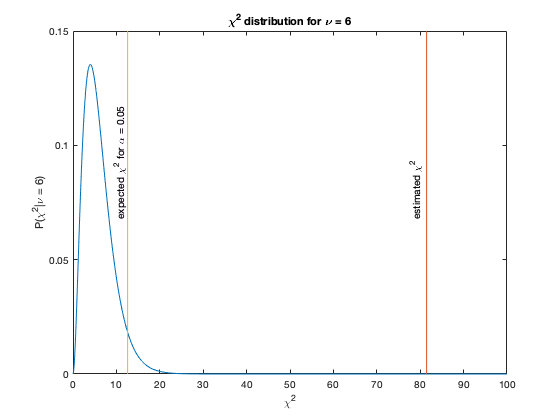

% plot chi^2 distribution
y = [0:0.1:100];
P = chi2pdf(y,nu);

figure;
hold on;
plot(y,P);
xlabel('\chi^2');
ylabel('P(\chi^2|\nu = 6)');
title(['\chi^2 distribution for \nu = ',num2str(nu)]);
plot(chi2*[1 1],[0 0.15],'-');
text(0.99*chi2,0.5*max(P),'estimated \chi^2','Rotation',90,'VerticalAlignment','bottom');
plot(chi2_expected*[1 1],[0 0.15],'-');
text(0.98*chi2_expected,0.5*max(P),'expected \chi^2 for \alpha = 0.05','Rotation',90,'VerticalAlignment','bottom');
set(gca,'Box','on');

### 5.4.5 Shapiro–Wilk test

$H_0$: A sample set is drawn from a normal distribution.

The Shapiro–Wilk tests whether a sample set distribution is drawn from a Gaussian population.


$$W = \frac{\sum_{i=1}^N a_i x_{(i)}}{\sum_{i=1}^N (x_i - \bar{x})^2}$$


where $x_{(i)}$ is $i$-th ordered sample value.  The coefficients $a_i$ are determined by the means, variance and covariance of the order statistics for $N$ samples.

### 5.4.6 Kolmogorov–Smirnov (K–S) test

The Kolomogorov–Smirnov (K–S) test examines whether a distribution comes from a reference continuous distribution (one-sample K–S test) or if two distributions are drawn from the same population (two-sample K–S test).  This test can be used in a similar manner to the Shapiro–Wilk test, but is less accurate at determining normality.  The advantage is that it can work for any arbitrary univariate distribution.

#### 5.4.6.1 One sample K–S test

$H_0$: A sample set is drawn from a known distribution.

The K–S test also provides some advantages over the t-test.  The t-test only examines differences from a true mean or a between two means.  However, the K–S test examines the distributions looking for the maximum difference between the distributions, which if large, may indicate that the two distributions are drawn from different populations.  The first step in performing a K–S test is to compute the empirical CDF from the sample set.  The K–S test statistic compared to a normal distribution can be summarized as


$$D = \max_{1\leq i \leq N} \left[ C(x_i) - \frac{i - 1}{N}, \frac{i}{N} - C(x_i)) \right]$$


where $x_i$ is $i$-th ordered value from the sample set and $C(x_i)$ is the empirical CDF.  This can also be written as


$$D = \sup_{x} | C_1(x) - C(x) |$$


where $\sup$ is the supermium function and $C(x)$ is the known continuous distribution.

The K–S test tends to be more sensitive to the center of the distribution than the tails.  An alternative test that performs somewhat better for a one sample test is the Anderson–Darling test.  However, for large sample sizes, most if not all tests for distribution similarity almost always reject the null hypothesis (i.e., that the distributions are drawn from the same population).

#### 5.4.6.1 Two sample K–S test

$H_0$: Two sample sets are drawn from the same population.

The two sample K–S test statistic is determined by finding the largest absolute deviation between the respective empirical CDF's for each sample set, i.e.,


$$D = \max_{1 \leq k \leq M} | C_1(x) - C_2(x) |$$


where $C_1$ and $C_2$ are the empirical CDF's and $M$ is the unique number of $x$ values of the combined sample sets.

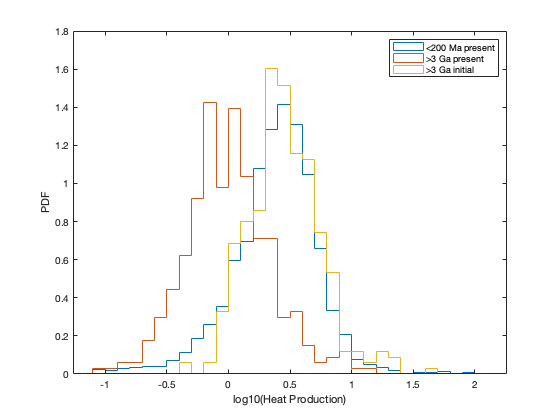

clear all;

data = readtable('granite_hp_age.xlsx');

ind1 = data.avg_age < 200;
ind2 = data.avg_age > 3000;

figure;
histogram(log10(data.heat_production(ind1)),'Normalization','pdf','DisplayStyle','stairs','BinWidth',0.1);
hold on;
histogram(log10(data.heat_production(ind2)),'Normalization','pdf','DisplayStyle','stairs','BinWidth',0.1);
histogram(log10(data.heat_production_init(ind2)),'Normalization','pdf','DisplayStyle','stairs','BinWidth',0.1);
legend('<200 Ma present','>3 Ga present','>3 Ga initial');
xlabel('log10(Heat Production)');
ylabel('PDF');

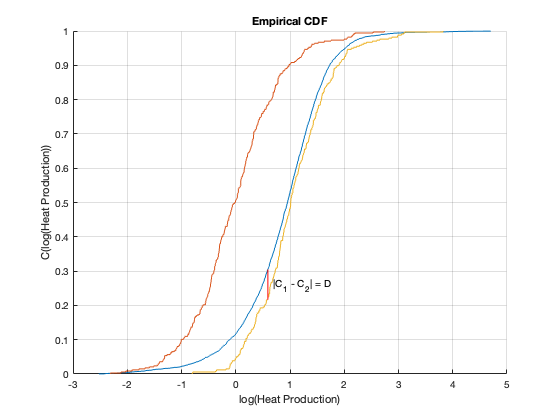

% compute two sample K-S statistic
[C1,x1] = ecdf(log(data.heat_production(ind1)));
%[C2,x2] = ecdf(log(data.heat_production(ind2)));
[C2,x2] = ecdf(log(data.heat_production_init(ind2)));

% combined locations
%x12 = unique(sort([x1;x2]));
x12 = unique(sort([x1;x2]));

D = 0; % K-S statistic (maximum deviation)
i = 1; % index of x1 and C1
j = 1; % index of x2 and C2
for k = 1:length(x12)
    % compute absolute deviation at x12
    Dtemp = abs(C1(i) - C2(j));
    % if absolute deviation of x12 is > current then update absolute
    % deviation
    if Dtemp > D
        D = Dtemp;
        c = [i j k];
    end

    % update i and j indicies to be consistent with 
    while x1(i) <= x12(k) & i < length(x1);
        i = i + 1;
    end
    if x1(i) > x12(k) & i ~= 1
        i = i - 1;
    end
    while x2(j) <= x12(k) & j < length(x2);
        j = j + 1;
    end
    if x2(j) > x12(k) & j ~= 1
        j = j - 1;
    end
end

% plot empirical CDF and position of maximum deviation
figure;
hold on;
cdfplot(log(data.heat_production(ind1)));
cdfplot(log(data.heat_production(ind2)));
cdfplot(log(data.heat_production_init(ind2)));
plot([x12(c(3)) x12(c(3))],[C1(c(1)) C2(c(2))],'r-');
text(x12(c(3))+0.1,(C1(c(1))+C2(c(2)))/2,'|C_1 - C_2| = D','HorizontalAlignment','left');
ylabel('C(log(Heat Production))');
xlabel('log(Heat Production)');

disp(['KS statistic:',num2str(D)])

KS statistic:0.087946



% We didn't need to compute the K-S statistic as we did above, matlab has a
% function in the statistics toolbox that can do so.
[H,p,ksstat] = kstest2(log(data.heat_production(ind1)),log(data.heat_production_init(ind2)),'Alpha',0.05)

H = logical
   1


p = 0.0158

ksstat = 0.0879

The hypothesis can be rejected at the 95% significance level, but not the 99% significance level because the p-value for our test statistic is 0.0158.

### 5.4.7 Anderson–Darling Test

$H_0$: A sample set is drawn from a known distribution.

Much like the one sample K–S test, the Anderson–Darling tests whether a sample set comes from a known distribution.  The test statistic gives more weight to the tails than the K–S test making it a more even test of difference.  The Anderson–Darling test statistic is computed by


$$A = \left[ -N - \sum_{i = 1}^N \frac{2i - 1}{N} \{ \log C(x_i) + \log (1 - C(x_{N+1-i}) \} \right]^{1/2}$$


where $x_i$ is $i$-th ordered value from the sample set and $C(x_i)$ is the empirical CDF.

## 5.5 Directional Statistical Tests

### 5.5.1 Circular

#### 5.5.1.1 Existence of a Mean test

$H_0$: The mean of a sample set and a known mean are equivalent.

The Raleigh $z$-test can be used to test whether there is a statistically significant mean.  The test statistic is simply determined by


$$z = NR^2$$


where $N$ is the number of samples and $R$ is the resultant length.

#### 5.5.1.2 Comparison of two distributions

$H_0$: The means of two sample sets are equivalent.

The Watson $U^2$-test examines whether two sample sets of angles have the similar principle azimuths.  To determine the test statistic, both sets of angles need to be ordered from smallest to largest.  You will need three indexes for set 1 ($i$), set 2 ($j$), and the combined ranked set ($k$).  Compute the frequencies for each set, $f_1(k) = i/N_1$ and $f_2(k) = j/N_2$, where $N_1$ and $N_2$ are the number of samples in each respective set.  If there is no angle a set associated with $k$, then the previous $i$ or $j$ is used.  The test statistic is then computed as,


$$U^2 = \frac{N_1 N_2}{(N_1 + N_2)^2} \left[ \sum_{k = 1}^{N_1 + N_2} (f_1(k) - f_2(k))^2 - \frac{1}{N_1 + N_2}\left( \sum_{k = 1}^{N_1 + N_2} f_1(k) - f_2(k) \right)^2 \right]$$


Let's look at an example, using downed trees.  We will test whether they have the same directionality.

clear all;

% load data
data = readtable('Corls_Ridge.xlsx')

data = 13×2 table
    group    direction
    _____    _________

     'A'        60    
     'A'        64    
     'A'        66    
     'A'        55    
     'A'        67    
     'A'        63    
     'A'        57    
     'B'        70    
     'B'        67    
     'B'        68    
     'B'        72    
     'B'        73    
     'B'        65    


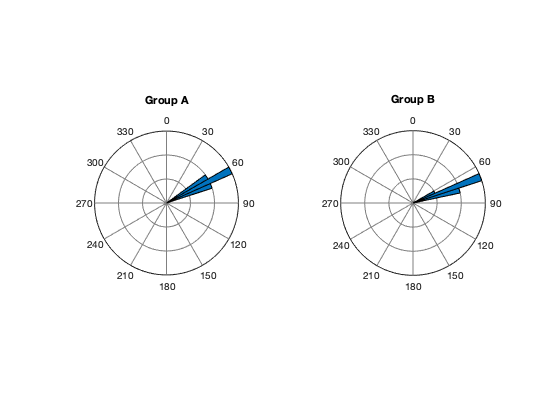


% sort all the angles in a common set
data = sortrows(data,2);

% indices of group A and B
indA = strcmp(data.group,'A');
indB = strcmp(data.group,'B');

figure;
subplot(121);
rosehist(data.direction(indA),60);
title('Group A');
subplot(122);
rosehist(data.direction(indB),60);
title('Group B');

A1 = data.direction(indA);
A2 = data.direction(indB);

% number of samples in groups A an B
Ni = sum(indA);
Nj = sum(indB);

% create i, j indices
data.i = cumsum(indA);
data.j = cumsum(indB);

% find and remove duplicate angles
c = 1;
while c < height(data)
    if data.direction(c) == data.direction(c+1)
        % if the duplicates come from different groups, combine the group
        % name
        if indA(c) == indB(c+1) | strcmp(data.group(c),'A/B');
            data.group{c+1} = 'A/B';
        end
        % delete current row, i.e., keep last duplicate since it will have
        % the correct i and j values for the entry.
        data(c,:) = [];
        % normally if I'm going to delete lines, I would save the data into
        % another variable before I start the process so I can still use,
        % or refer to the original data if necessary.  In this example, the
        % whole point is statistical test.
    else
        c = c + 1;
    end
end
data.fi = data.i/Ni;
data.fj = data.j/Nj;

data

data = 12×6 table
    group    direction    i    j      fi         fj   
    _____    _________    _    _    _______    _______

    'A'         55        1    0    0.14286          0
    'A'         57        2    0    0.28571          0
    'A'         60        3    0    0.42857          0
    'A'         63        4    0    0.57143          0
    'A'         64        5    0    0.71429          0
    'B'         65        5    1    0.71429    0.16667
    'A'         66        6    1    0.85714    0.16667
    'A/B'       67        7    2          1    0.33333
    'B'         68        7    3          1        0.5
    'B'         70        7    4          1    0.66667
    'B'         72        7    5          1    0.83333
    'B'         73        7    6          1          1


U2 = Ni*Nj/(Ni+Nj)^2*(sum((data.fi - data.fj).^2) - (sum(data.fi - data.fj))^2/(Ni+Nj))

U2 = 0.1920

% clear the memory since we need to reload data
clear all;

data = readtable('Corls_Ridge.xlsx');
[U2_obs,p] = watsons_U2(data)

U2_obs = 0.1920

p = 0.0292

[U2_obs,U2_alpha] = watsons_U2(data,0.05)

U2_obs = 0.1920

U2_alpha = 0.1721

Both the estimated p-value of $\sim$0.04 < 0.05 so the null hypothesis must be rejected.

#### 5.5.1.2 Uniformity test

$H_0$: The sample set is uniformly distributed.

To test for uniformity (even distribution of angles) 

### 5.5.2 Spherical

Another time perhaps.  Paleomag!

## 5.6 Sequence Tests

### 5.6.1 Run Test

$H_0$: A sequence is random (contains no trend).

The run test comes in handy in at least circumstances, first when examining data in sequence to ensure that the data are in fact random and second when examining a model fit to data to determine whether or not a model is appropriate.

Let's look at a simple example using coin tosses and then we'll return to science.  If I take a coin and toss it four times, I can get 16 potential solutions: TTTT, TTTH, TTHT, THTT, HTTT, TTHH, THTH, HTTH, THHT, HTHT, HHTT, THHH, HTHH, HHTH, HHHT, and HHHH.  Starting with 1, I add the number of times that consecutive tosses in a sequence change from T to H or H to T.  So for TTTT, the number of runs would be 1.  For TTTH, 2, and for TTHT, 3.  The frequency of the number of runs for all the sequences is given in the table below.


$$\begin{array}{cc} \text{Number of runs} & \text{Number of sample sets} \\ 1 & 2 \\ 2 & 6 \\ 3 & 6 \\ 4 & 2 \end{array}$$


$\text{Pr}(x|y)$ means the probability of $x$ happening given $y$, in this case $y$ is the number of coin tosses and $x$ is the number of runs.  We can use these to compute the probability of one run is $\text{Pr}(1|4) = 2/16 = 0.125$, and the probability of two runs is $\text{Pr}(2|4) = 6/16 = 0.375$.  As I increase the number of coin tosses in a sequence, $\text{Pr}(1|5) = 0.0625$ and $\text{Pr}(5|5) = 0.0625$.  Therefore, as the number of tosses grow, the number of both low and high frequency runs become small.

How do we use this information?  Suppose you are collecting data on an instrument (say an IRMS).  If you run a bunch of standards, you will need to determine whether the noise is random or requires some drift correction.  If the data are random, they will vary about the median value and when in sequence, consecutive samples will be both above, both below or one above and one below, varying between the three options with some frequency.  Since the values are irrelevant for this test, only whether they fall above or below the mean, we may simply keep track of the sign of above or below.  If the number of switches in sign is too low, the probability that we would observe such an even is very low.  Therefore, we may examine the data for a systematic variation that possibly relates to a drift.

If we are testing a physical model, we use the signed residual values instead of the median value.  If the number of switches in sign is too low, the model may be incorrect, e.g., fitting a line to a quadratic data.  If the switches in sign are too large, then we might examine the possibility of overfitting the data.

There are a number of physical models for the cooling of an oceanic plate.  Two physical models can be shown to fit heat flow data about equally well in misfit.  As shown by the result below.

If we closely examine the residuals, you will see that one model appears to have a systematic variation in the residuals with respect to the data.

By performing a run test we can determine whether one or both models are viable solutions or whether one can be excluded as a possible physical solution.

### 5.6.2 Change Point Test

$H_0$: No change point exists.

A change point test examines whether there is a shift in the mean, variance, correlation, or spectral density of a series (spatial or temporal) at an unknown point.  As examples, this class of tests could be used to examine changes in paleoclimate or the edges of structures from changes in geophysical fields or the change in chemistry of a vertical or lateral sedimentary sequence due to a shift from freshwater to marine environment.  We will look at the Pettitt test, which is one of the simpler change point tests.  Unfortunately the Pettitt test can only explore for a single change point.  To find multiple change points, the record can be broken up as change points are identified and break the record into parts.  There are other more complex methods exist that can identify multiple change points.

The Pettitt test is a nonparametric test computed from the rank-order.  The Pettitt-statistic at location $i$, for the ranks $R = \{r_1, r_2, \ldots, r_N\}$ associated with the data $X = \{ x_1, x_2, \ldots, x_N \}$ is given by


$$U_i = 2 \sum_{j = 1}^i r_j - i (N + 1)$$


The test statistic for the Pettitt test is $U^* = \max | U_i |$, which is located at index $k$.

The probability can be approximated by


$$p = 2 \exp \left( - \frac{6 k^2}{N^2(N + 1)} \right)$$


## 5.7 Outliers

When a point is an outlier and how to handle them generates vigorous debates among scientists.  There is no single uniformly accepted method for handling outliers.  Some would say if they are $>3\sigma$ from the mean then the point should be discarded.  Others will suggest that they should never be tossed, but downweighted.  And Ernest Rutherford said "If your experiment needs statistics, you ought to have done a better experiment."  But outliers happen and statistics can help guide the way.  If you throw a point out, make sure you have a damn good reason to do so because there are ***serious scientific ethical considerations*** about excluding data.  Some scientists have lost their jobs and even careers for unethically excluding data to conform to their personal bias.  If you do chose to throw data out, then you should document why and include the outlier on plots so that others can assess the validity of your choice, limiting the ethical concerns.  Also if you do remove outliers from any analysis, you should make sure that you compute the model with and without the data so that you can quantify the impact on the final model and interpretation.

One last point to be made before we learn how to treat them statistically is to consider what an outlier may represent.  Outliers can in some cases yield important information about processes, perhaps undiscovered, or in some cases like mineral exploration...*outliers are the targets!*

A better way to handle outliers is to collect additional data, if possible, so that the underlying distribution can be better modeled with the outlier included.  If you have enough data, an outlier is just an unremarkable data point in the tail of a distribution.  However, collecting more data can be expensive or impossible (e.g., destructive measurement, limited quantities, inaccessibility of samples) or the data are part of a sequence that cannot be repeated (e.g., time-series).

Removing outliers are best if a rule can be established of which there are two types: process and statistical.  A process rule will exclude data that result from an unwanted physical or chemical process.  For example, weathering can alter the geochemistry of samples, generally in a predictive way.  If weathering is not under consideration as part of your study, you might define a restricted range of chemistries that excludes values or trends that occur as a result.  If you choose a such a rule, you can rely on previously published studies, or you may have to demonstrate the source of deviations yourself, often requiring extensive analysis.

Statisical rules can be simple for univariate data.  Simply set a range of deviation from the mean, e.g., $>3\sigma$ as mentioned above, $1.5 * \text{IQR}$.  I have seen it recommended that for some machine learning methods the effects of outliers are so profound on the resultant classifier that it is best to remove data outside the 5 and 95% quantiles from the mean.  Again, if you choose such a method, you should test the result with and without the restriction yourself because it may not be necessary in all cases.

For multivariate statistical methods, outlier detection methods are recommended.  Outlier detection is a set of automated procedures for removing outliers.  We will discuss outliers further in Section 6.7 in the chapter on regression.